%Model Geometric-Geometrie directa
%intrare:variabile din cuple
 q1=0; %rotatie
 q2=0; %rotatie
 q3=0; %rotatie
 q4=0; %rotatie
 q5=0; %rotatie
 %iesire:vectorul de pozitie al efectorului
[punct]= incercarelicentageometriedirecta(q1,q2,q3,q4,q5)

T10=
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1

T21=
     1     0     0     0
     0     1     0     0
     0     0     1    20
     0     0     0     1

T32=
     1     0     0     0
     0     1     0     0
     0     0     1   105
     0     0     0     1

T43=
     1     0     0     0
     0     1     0     0
     0     0     1   145
     0     0     0     1

T54=
     1     0     0     0
     0     1     0     0
     0     0     1    70
     0     0     0     1

Te5
     1     0     0     0
     0     1     0     0
     0     0     1   110
     0     0     0     1

Te0=
     1     0     0     0
     0     1     0     0
     0     0     1   450
     0     0     0     1



punct =      0
     0
   450
     1


[q1,q2,q3,q4,q5,T10,T21,T32,T43,T54,Te5,Te0] = geometrie_directa_simboliclicentabuna()

$$q1 = q_{1}$$

$$q2 = q_{2}$$

$$q3 = q_{3}$$

$$q4 = q_{4}$$

$$q5 = q_{5}$$

$$T10 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T21 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T32 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ 0 & \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T43 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0\\ 0 & \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T54 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Te5 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Te0_simplified = simplify(subs(Te0));
disp(Te0_simplified);

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{5}\right)-\sigma_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{5}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)-\sigma_{1}\,\cos\left(q_{5}\right)\,\sin\left(q_{1}\right) & \sigma_{3}\,\sin\left(q_{1}\right) & 5\,\sin\left(q_{1}\right)\,\sigma_{2}\\ \cos\left(q_{5}\right)\,\sin\left(q_{1}\right)+\sigma_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{5}\right) & \sigma_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{5}\right) & -\sigma_{3}\,\cos\left(q_{1}\right) & -5\,\cos\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(q_{5}\right) & \sigma_{3}\,\cos\left(q_{5}\right) & \sigma_{1} & 180\,\sigma_{1}+145\,\cos\left(q_{2}+q_{3}\right)+105\,\cos\left(q_{2}\right)+20\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=36\,\sigma_{3}+29\,\sin\left(q_{2}+q_{3}\right)+21\,\sin\left(q_{2}\right)\\ \sigma_{3}=\sin\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

% Înlocuire completă
Te0_num = double(subs(Te0_simplified, ...
    [q1, q2, q3, q4, q5, l1, l2, l3, l4, l5], ...
    [0, 0, 0, 0, 0, 20, 105, 145, 70, 110]));  % <- valorile efective

% === AFIȘARE
disp(Te0_num)

     1     0     0     0
     0     1     0     0
     0     0     1   450
     0     0     0     1



%Jacobian

[q1,q2,q3,q4,q5,T10,T21,T32,T43,T54,Te5,Te0] = geometrie_directa_simboliclicentabuna()

$$q1 = q_{1}$$

$$q2 = q_{2}$$

$$q3 = q_{3}$$

$$q4 = q_{4}$$

$$q5 = q_{5}$$

$$T10 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T21 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T32 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ 0 & \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T43 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0\\ 0 & \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T54 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Te5 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[J] = Jacobian(q1,q2,q3,q4,q5,T10,T21,T32,T43,T54,Te5)

T01=


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tw1=


$$\left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

T02=


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tw2=


$$\left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

T03=


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & l_{1}+l_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tw3=


$$\left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

T04=


$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{1}\right) & \cos\left(q_{4}\right)\,\sigma_{4}+\sin\left(q_{4}\right)\,\sigma_{1} & \cos\left(q_{4}\right)\,\sigma_{1}-\sin\left(q_{4}\right)\,\sigma_{4} & l_{3}\,\sigma_{1}+l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{4}\right)\,\sigma_{5}-\sin\left(q_{4}\right)\,\sigma_{2} & -\cos\left(q_{4}\right)\,\sigma_{2}-\sin\left(q_{4}\right)\,\sigma_{5} & -l_{3}\,\sigma_{2}-l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{4}\right)\,\sigma_{6}+\sin\left(q_{4}\right)\,\sigma_{3} & \cos\left(q_{4}\right)\,\sigma_{3}-\sin\left(q_{4}\right)\,\sigma_{6} & l_{1}+l_{3}\,\sigma_{3}+l_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{4}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{5}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}$$

Tw4=


$$\left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

T05=


Tw5=


$$\left(\begin{array}{c} \cos\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-\sin\left(q_{4}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)\\ -\cos\left(q_{4}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)-\sin\left(q_{4}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)\\ \cos\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-\sin\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right) \end{array}\right)$$

T0e=


pe=


$$\begin{array}{l} \left(\begin{array}{c} l_{3}\,\sigma_{4}+l_{4}\,\sigma_{2}+l_{5}\,\sigma_{2}+l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -l_{3}\,\sigma_{5}-l_{4}\,\sigma_{3}-l_{5}\,\sigma_{3}-l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ l_{1}+l_{3}\,\left(\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sigma_{1}+l_{5}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-\sin\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{2}=\cos\left(q_{4}\right)\,\sigma_{4}-\sin\left(q_{4}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)\\ \sigma_{3}=\cos\left(q_{4}\right)\,\sigma_{5}+\sin\left(q_{4}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)\\ \sigma_{4}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{5}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}$$

symvar(J)

$$ans = \left(\begin{array}{cccccccc} l_{2} & l_{3} & l_{4} & l_{5} & q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

% Definirea valorilor
J_simplified = simplify(subs(J));
disp('Jacobian simplificat')

Jacobian simplificat


disp(J_simplified)

$$\begin{array}{l} \left(\begin{array}{ccccc} \cos\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sigma_{2} & \sin\left(q_{1}\right)\,\sigma_{3} & \sigma_{6}\,\sin\left(q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ \sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{3} & -\sigma_{6}\,\cos\left(q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ 0 & -\sigma_{5}-l_{2}\,\sin\left(q_{2}\right)-l_{4}\,\sigma_{4}-l_{5}\,\sigma_{4} & -\sigma_{5}-l_{4}\,\sigma_{4}-l_{5}\,\sigma_{4} & -\sigma_{4}\,\left(l_{4}+l_{5}\right) & 0\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \sigma_{4}\,\sin\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & -\sigma_{4}\,\cos\left(q_{1}\right)\\ 1 & 0 & 0 & 0 & \sigma_{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{5}+l_{2}\,\sin\left(q_{2}\right)+l_{4}\,\sigma_{4}+l_{5}\,\sigma_{4}\\ \sigma_{2}=\sigma_{7}+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sigma_{6}+l_{5}\,\sigma_{6}\\ \sigma_{3}=\sigma_{7}+l_{4}\,\sigma_{6}+l_{5}\,\sigma_{6}\\ \sigma_{4}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{5}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{7}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

[Jz] = Jacobianincercare2(q1,q2,q3,q4,q5,T10,T21,T32,T43,T54,Te5)

J_simplified2 = simplify(subs(Jz));
disp('Jacobian simplificat')

Jacobian simplificat


disp(J_simplified2)

$$\begin{array}{l} \left(\begin{array}{ccccc} \cos\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sigma_{2} & \sin\left(q_{1}\right)\,\sigma_{3} & \sigma_{6}\,\sin\left(q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ \sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{3} & -\sigma_{6}\,\cos\left(q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ 0 & -\sigma_{5}-l_{2}\,\sin\left(q_{2}\right)-l_{4}\,\sigma_{4}-l_{5}\,\sigma_{4} & -\sigma_{5}-l_{4}\,\sigma_{4}-l_{5}\,\sigma_{4} & -\sigma_{4}\,\left(l_{4}+l_{5}\right) & 0\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \sigma_{4}\,\sin\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & -\sigma_{4}\,\cos\left(q_{1}\right)\\ 1 & 0 & 0 & 0 & \sigma_{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{5}+l_{2}\,\sin\left(q_{2}\right)+l_{4}\,\sigma_{4}+l_{5}\,\sigma_{4}\\ \sigma_{2}=\sigma_{7}+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sigma_{6}+l_{5}\,\sigma_{6}\\ \sigma_{3}=\sigma_{7}+l_{4}\,\sigma_{6}+l_{5}\,\sigma_{6}\\ \sigma_{4}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{5}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{7}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

% Înlocuire completă
%J_num = double(subs(J_simplified, ...
 %   [q1, q2, q3, q4, q5, l1, l2, l3, l4, l5], ...
 %   [pi, pi/2, pi/2, pi/2, pi, 20, 105, 145, 70, 110]));  % <- valorile efective

% === AFIȘARE JACOBIANĂ NUMERICĂ ===
%disp(J_num)

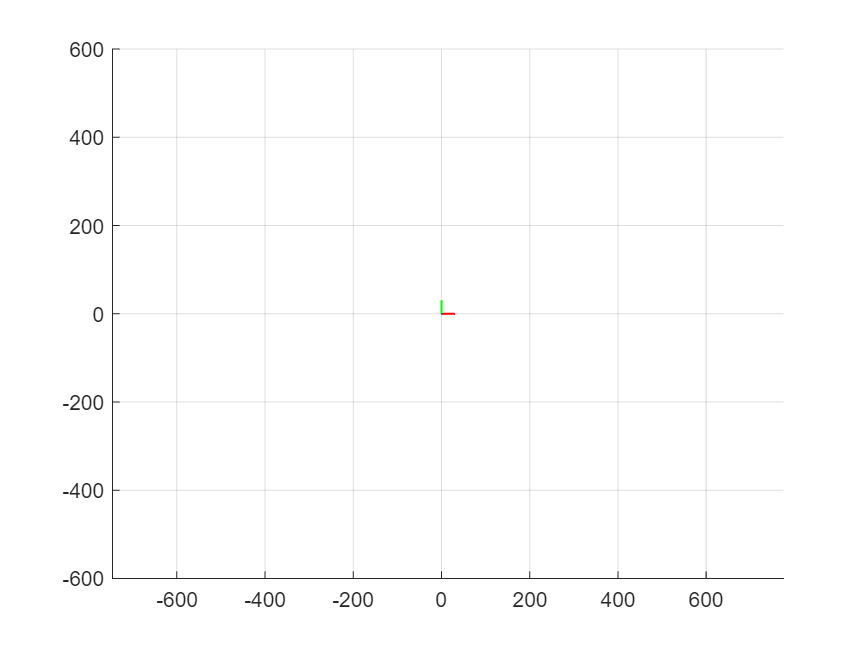

T10 =
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1

T21 =
     1     0     0     0
     0     1     0     0
     0     0     1    20
     0     0     0     1

T32 =
     1     0     0     0
     0     1     0     0
     0     0     1   105
     0     0     0     1

T43 =
     1     0     0     0
     0     1     0     0
     0     0     1   145
     0     0     0     1

T54 =
     1     0     0     0
     0     1     0     0
     0     0     1    70
     0     0     0     1

Te5 =
     1     0     0     0
     0     1     0     0
     0     0     1   450
     0     0     0     1



%Reprezentare configuratie(Desen)
%intrare: Variabile din cuple
 q1=0; %rotatie 
 q2=0; %rotatie 
 q3=0; %rotatie
 q4=0; %rotatie
 q5=0; %rotatie
 %iesire:vectorul de pozitie al efectorului
 desenMGDlicentabuna(q1,q2,q3,q4,q5)

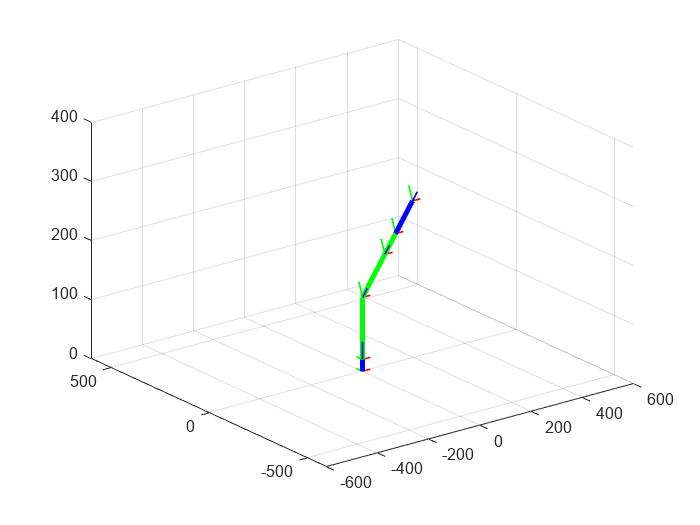

%Geometrie directa pseudoanimatie
%intrare: variabilele din cuple
%iesire: pozitia efectorului 
q1=0; 
q2=0; 
q3=pi/2; 
q4=pi/2;
q5=0;
animatie(q1,q2,q3,q4,q5)

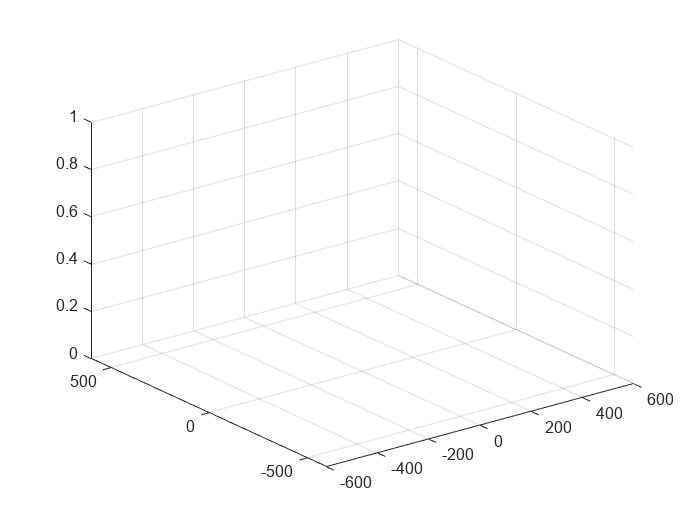

Q =     2.3420
   -0.3336
    0.8417
    2.0154
    0.7854


clc
%Geometrie inversa
%intrare: pozitia efectorului
%iesire: pozitia cuplelor
Pe = [100; 100; 100;1];
[Q]= Geometrie_inversa_simboliclicenta(Pe)

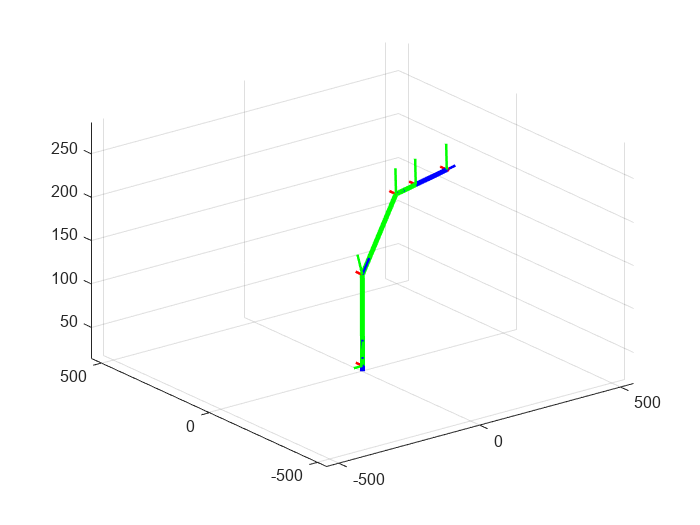

Q =     1.5663
   -0.0060
    0.9712
    0.5358
         0


clc
%Geometrie inversa
%intrare: pozitia efectorului
%iesire: pozitia cuplelor
Pe = [300; 0; 220]; % milimetri
[Q]= geometrieinversalicenta(Pe)

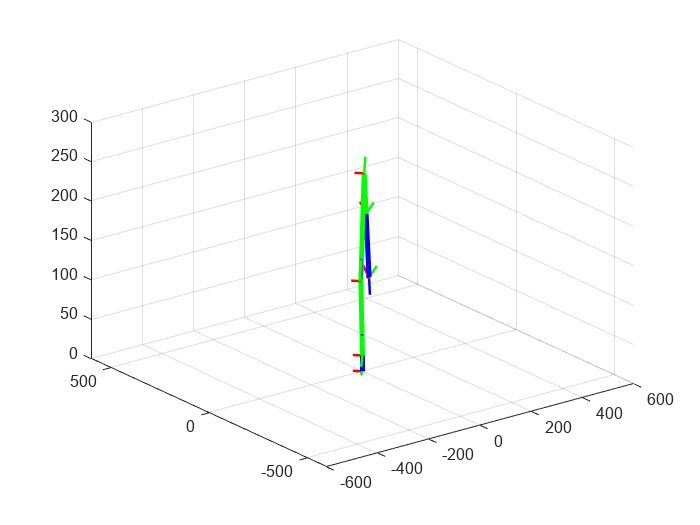

Q =     2.3420
   -0.3336
    0.8417
    2.0154
    0.7854


clc
%Geometrie inversa
%intrare: pozitia efectorului
%iesire: pozitia cuplelor
Pe = [100; 100; 100]; % milimetri
[Q]= geometrieinversalicentaincercare2(Pe)

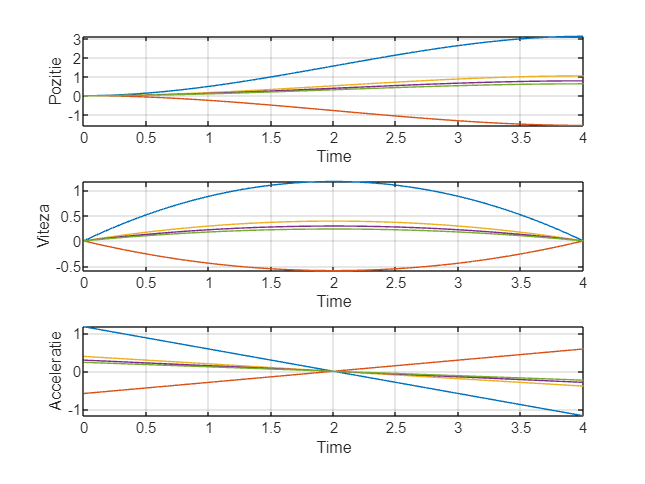

a0
     0
     0
     0
     0
     0

a1
     0

a2
    0.5890
   -0.2945
    0.1963
    0.1473
    0.1178

a3
   -0.0982
    0.0491
   -0.0327
   -0.0245
   -0.0196



qt =          0    0.0010    0.0038    0.0085    0.0150    0.0232    0.0332    0.0449    0.0582    0.0732    0.0897    0.1077    0.1273    0.1483    0.1707    0.1945    0.2196    0.2461    0.2738    0.3027    0.3328    0.3641    0.3965    0.4299    0.4644    0.4998    0.5362    0.5736    0.6118    0.6508    0.6906    0.7312    0.7725    0.8145    0.8571    0.9003    0.9441    0.9884    1.0332    1.0785    1.1241    1.1702    1.2165    1.2632    1.3101    1.3572    1.4045    1.4519    1.4994    1.5470
         0   -0.0005   -0.0019   -0.0042   -0.0075   -0.0116   -0.0166   -0.0224   -0.0291   -0.0366   -0.0448   -0.0539   -0.0636   -0.0741   -0.0854   -0.0973   -0.1098   -0.1230   -0.1369   -0.1514   -0.1664   -0.1821   -0.1982   -0.2150   -0.2322   -0.2499   -0.2681   -0.2868   -0.3059   -0.3254   -0.3453   -0.3656   -0.3863   -0.4072   -0.4286   -0.4502   -0.4721   -0.4942   -0.5166   -0.5392   -0.5621   -0.5851   -0.6083   -0.6316   -0.6550   -0.6786   -0.7022   -0.7259   -0.7497   -

viteza =          0    0.0471    0.0933    0.1385    0.1827    0.2260    0.2683    0.3096    0.3500    0.3895    0.4279    0.4654    0.5020    0.5375    0.5722    0.6058    0.6385    0.6702    0.7010    0.7308    0.7597    0.7876    0.8145    0.8405    0.8655    0.8895    0.9126    0.9347    0.9558    0.9760    0.9953    1.0135    1.0309    1.0472    1.0626    1.0770    1.0905    1.1030    1.1145    1.1251    1.1347    1.1434    1.1511    1.1578    1.1636    1.1684    1.1722    1.1751    1.1770    1.1780
         0   -0.0236   -0.0466   -0.0692   -0.0914   -0.1130   -0.1341   -0.1548   -0.1750   -0.1947   -0.2140   -0.2327   -0.2510   -0.2688   -0.2861   -0.3029   -0.3193   -0.3351   -0.3505   -0.3654   -0.3798   -0.3938   -0.4072   -0.4202   -0.4327   -0.4447   -0.4563   -0.4673   -0.4779   -0.4880   -0.4976   -0.5068   -0.5154   -0.5236   -0.5313   -0.5385   -0.5452   -0.5515   -0.5573   -0.5625   -0.5674   -0.5717   -0.5755   -0.5789   -0.5818   -0.5842   -0.5861   -0.5875   -0.5885

acceleratie =     1.1781    1.1543    1.1305    1.1067    1.0829    1.0591    1.0353    1.0115    0.9877    0.9639    0.9401    0.9163    0.8925    0.8687    0.8449    0.8211    0.7973    0.7735    0.7497    0.7259    0.7021    0.6783    0.6545    0.6307    0.6069    0.5831    0.5593    0.5355    0.5117    0.4879    0.4641    0.4403    0.4165    0.3927    0.3689    0.3451    0.3213    0.2975    0.2737    0.2499    0.2261    0.2023    0.1785    0.1547    0.1309    0.1071    0.0833    0.0595    0.0357    0.0119
   -0.5890   -0.5771   -0.5652   -0.5533   -0.5414   -0.5295   -0.5176   -0.5057   -0.4938   -0.4819   -0.4700   -0.4581   -0.4462   -0.4343   -0.4224   -0.4105   -0.3986   -0.3867   -0.3748   -0.3629   -0.3510   -0.3391   -0.3272   -0.3153   -0.3034   -0.2915   -0.2796   -0.2677   -0.2558   -0.2439   -0.2320   -0.2201   -0.2082   -0.1963   -0.1844   -0.1725   -0.1606   -0.1487   -0.1368   -0.1249   -0.1130   -0.1011   -0.0892   -0.0773   -0.0654   -0.0535   -0.0416   -0.0297   -0

t =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798


%Calculul variabilelor generalizare(pick and place)
%intrare:coordonate puncte,durata
%iesire :pozitie,viteza si acceleratie

Q_initial = [0; 0; 0; 0; 0]; % Punct de plecare
Q_final = [pi;-pi/2;pi/3;pi/4;pi/5];   % Punct destinatie
[qt,viteza,acceleratie,t]=PickandPlace(Q_initial,Q_final,4)

qt1=[t',qt(1,:)']

qt1 =          0         0
    0.0404    0.0010
    0.0808    0.0038
    0.1212    0.0085
    0.1616    0.0150
    0.2020    0.0232
    0.2424    0.0332
    0.2828    0.0449
    0.3232    0.0582
    0.3636    0.0732


qt2=[t',qt(2,:)']

qt2 =          0         0
    0.0404   -0.0005
    0.0808   -0.0019
    0.1212   -0.0042
    0.1616   -0.0075
    0.2020   -0.0116
    0.2424   -0.0166
    0.2828   -0.0224
    0.3232   -0.0291
    0.3636   -0.0366


qt3=[t',qt(3,:)']

qt3 =          0         0
    0.0404    0.0003
    0.0808    0.0013
    0.1212    0.0028
    0.1616    0.0050
    0.2020    0.0077
    0.2424    0.0111
    0.2828    0.0150
    0.3232    0.0194
    0.3636    0.0244


qt4=[t',qt(4,:)']

qt4 =          0         0
    0.0404    0.0002
    0.0808    0.0009
    0.1212    0.0021
    0.1616    0.0037
    0.2020    0.0058
    0.2424    0.0083
    0.2828    0.0112
    0.3232    0.0146
    0.3636    0.0183


qt5=[t',qt(5,:)']

qt5 =          0         0
    0.0404    0.0002
    0.0808    0.0008
    0.1212    0.0017
    0.1616    0.0030
    0.2020    0.0046
    0.2424    0.0066
    0.2828    0.0090
    0.3232    0.0116
    0.3636    0.0146



v1=[t',viteza(1,:)']

v1 =          0         0
    0.0404    0.0471
    0.0808    0.0933
    0.1212    0.1385
    0.1616    0.1827
    0.2020    0.2260
    0.2424    0.2683
    0.2828    0.3096
    0.3232    0.3500
    0.3636    0.3895


v2=[t',viteza(2,:)']

v2 =          0         0
    0.0404   -0.0236
    0.0808   -0.0466
    0.1212   -0.0692
    0.1616   -0.0914
    0.2020   -0.1130
    0.2424   -0.1341
    0.2828   -0.1548
    0.3232   -0.1750
    0.3636   -0.1947


v3=[t',viteza(3,:)']

v3 =          0         0
    0.0404    0.0157
    0.0808    0.0311
    0.1212    0.0462
    0.1616    0.0609
    0.2020    0.0753
    0.2424    0.0894
    0.2828    0.1032
    0.3232    0.1167
    0.3636    0.1298


v4=[t',viteza(4,:)']

v4 =          0         0
    0.0404    0.0118
    0.0808    0.0233
    0.1212    0.0346
    0.1616    0.0457
    0.2020    0.0565
    0.2424    0.0671
    0.2828    0.0774
    0.3232    0.0875
    0.3636    0.0974


v5=[t',viteza(5,:)']

v5 =          0         0
    0.0404    0.0094
    0.0808    0.0187
    0.1212    0.0277
    0.1616    0.0365
    0.2020    0.0452
    0.2424    0.0537
    0.2828    0.0619
    0.3232    0.0700
    0.3636    0.0779



acc1=[t',acceleratie(1,:)']

acc1 =          0    1.1781
    0.0404    1.1543
    0.0808    1.1305
    0.1212    1.1067
    0.1616    1.0829
    0.2020    1.0591
    0.2424    1.0353
    0.2828    1.0115
    0.3232    0.9877
    0.3636    0.9639


acc2=[t',acceleratie(2,:)']

acc2 =          0   -0.5890
    0.0404   -0.5771
    0.0808   -0.5652
    0.1212   -0.5533
    0.1616   -0.5414
    0.2020   -0.5295
    0.2424   -0.5176
    0.2828   -0.5057
    0.3232   -0.4938
    0.3636   -0.4819


acc3=[t',acceleratie(3,:)']

acc3 =          0    0.3927
    0.0404    0.3848
    0.0808    0.3768
    0.1212    0.3689
    0.1616    0.3610
    0.2020    0.3530
    0.2424    0.3451
    0.2828    0.3372
    0.3232    0.3292
    0.3636    0.3213


acc4=[t',acceleratie(4,:)']

acc4 =          0    0.2945
    0.0404    0.2886
    0.0808    0.2826
    0.1212    0.2767
    0.1616    0.2707
    0.2020    0.2648
    0.2424    0.2588
    0.2828    0.2529
    0.3232    0.2469
    0.3636    0.2410


acc5=[t',acceleratie(5,:)']

acc5 =          0    0.2356
    0.0404    0.2309
    0.0808    0.2261
    0.1212    0.2213
    0.1616    0.2166
    0.2020    0.2118
    0.2424    0.2071
    0.2828    0.2023
    0.3232    0.1975
    0.3636    0.1928


aux=reshape(out.moment1.Data,1,[])';
moment1=[out.moment1.Time,aux]

moment1 =          0    0.0336
    0.0800    0.0336
    0.1600    0.0339
    0.2400    0.0344
    0.3200    0.0350
    0.4000    0.0357
    0.4800    0.0366
    0.5600    0.0374
    0.6400    0.0382
    0.7200    0.0389


aux=reshape(out.moment2.Data,1,[])';
moment2=[out.moment2.Time,aux]

moment2 =          0   -0.0568
    0.0800   -0.0576
    0.1600   -0.0600
    0.2400   -0.0639
    0.3200   -0.0693
    0.4000   -0.0761
    0.4800   -0.0842
    0.5600   -0.0935
    0.6400   -0.1039
    0.7200   -0.1153


aux=reshape(out.moment3.Data,1,[])';
moment3=[out.moment3.Time,aux]

moment3 =          0   -0.0220
    0.0800   -0.0223
    0.1600   -0.0231
    0.2400   -0.0245
    0.3200   -0.0263
    0.4000   -0.0286
    0.4800   -0.0313
    0.5600   -0.0342
    0.6400   -0.0374
    0.7200   -0.0407


aux=reshape(out.moment1.Data,1,[])';
moment4=[out.moment4.Time,aux]

moment4 =          0    0.0336
    0.0800    0.0336
    0.1600    0.0339
    0.2400    0.0344
    0.3200    0.0350
    0.4000    0.0357
    0.4800    0.0366
    0.5600    0.0374
    0.6400    0.0382
    0.7200    0.0389


aux=reshape(out.moment2.Data,1,[])';
moment5=[out.moment5.Time,aux]

moment5 =          0   -0.0568
    0.0800   -0.0576
    0.1600   -0.0600
    0.2400   -0.0639
    0.3200   -0.0693
    0.4000   -0.0761
    0.4800   -0.0842
    0.5600   -0.0935
    0.6400   -0.1039
    0.7200   -0.1153


%Cinematica directa
%intrare: pozitie si viteza
%iesire: viteza liniara si unghiulara

[viteza_lineara,omega]=Cinematica_Directa(qt,viteza)

viteza_lineara =          0    0.8424    1.6674    2.4745    3.2637    4.0346    4.7869    5.5206    6.2354    6.9311    7.6076    8.2647    8.9024    9.5204   10.1186   10.6971   11.2557   11.7944   12.3130   12.8117   13.2902   13.7488   14.1872   14.6056   15.0040   15.3823   15.7408   16.0793   16.3980   16.6970   16.9764   17.2362   17.4766   17.6977   17.8996   18.0825   18.2465   18.3919   18.5187   18.6271   18.7174   18.7898   18.8444   18.8814   18.9012   18.9039   18.8897   18.8590   18.8119   18.7487
         0    0.8333    1.6492    2.4477    3.2285    3.9912    4.7359    5.4622    6.1700    6.8592    7.5296    8.1810    8.8135    9.4268   10.0208   10.5956   11.1509   11.6868   12.2033   12.7002   13.1776   13.6354   14.0736   14.4923   14.8914   15.2710   15.6312   15.9719   16.2932   16.5952   16.8780   17.1416   17.3862   17.6119   17.8187   18.0069   18.1765   18.3276   18.4605   18.5753   18.6721   18.7511   18.8126   18.8567   18.8836   18.8935   18.8867   18.8633  

omega =          0    0.0040    0.0079    0.0118    0.0156    0.0192    0.0228    0.0264    0.0298    0.0332    0.0364    0.0396    0.0427    0.0458    0.0487    0.0516    0.0544    0.0571    0.0597    0.0622    0.0647    0.0671    0.0694    0.0716    0.0737    0.0758    0.0778    0.0796    0.0814    0.0832    0.0848    0.0864    0.0879    0.0893    0.0906    0.0918    0.0930    0.0940    0.0950    0.0959    0.0968    0.0975    0.0982    0.0988    0.0993    0.0997    0.1000    0.1003    0.1004    0.1005
         0   -0.0041   -0.0082   -0.0121   -0.0160   -0.0198   -0.0235   -0.0271   -0.0307   -0.0341   -0.0375   -0.0408   -0.0440   -0.0471   -0.0501   -0.0530   -0.0559   -0.0587   -0.0614   -0.0640   -0.0665   -0.0689   -0.0713   -0.0736   -0.0757   -0.0778   -0.0799   -0.0818   -0.0836   -0.0854   -0.0871   -0.0887   -0.0902   -0.0916   -0.0929   -0.0942   -0.0954   -0.0965   -0.0975   -0.0984   -0.0992   -0.1000   -0.1006   -0.1012   -0.1017   -0.1021   -0.1024   -0.1027   -0.1028 

%Cinematica inversa
%intrare: viteza liniara,viteza unghiulara,variabila generalizata
%iesire: viteza generalizata
viteza_spatiala = [viteza_lineara; omega];
[viteza_generalizata]=Cinematica_Inversa(qt,viteza_spatiala)

viteza_generalizata =          0    0.0001    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018
         0    0.0024    0.0047    0.0069    0.0091    0.0113    0.0134    0.0155    0.0175    0.0195    0.0214    0.0233    0.0251    0.0269    0.0286    0.0303    0.0320    0.0335    0.0351    0.0366    0.0380    0.0394    0.0408    0.0421    0.0433    0.0445    0.0457    0.0468    0.0478    0.0488    0.0498    0.0507    0.0516    0.0524    0.0532    0.0539    0.0546    0.0552    0.0558    0.0563    0.0568    0.0572    0.0576    0.0579    0.0582    0.0585    0.0587    0.0

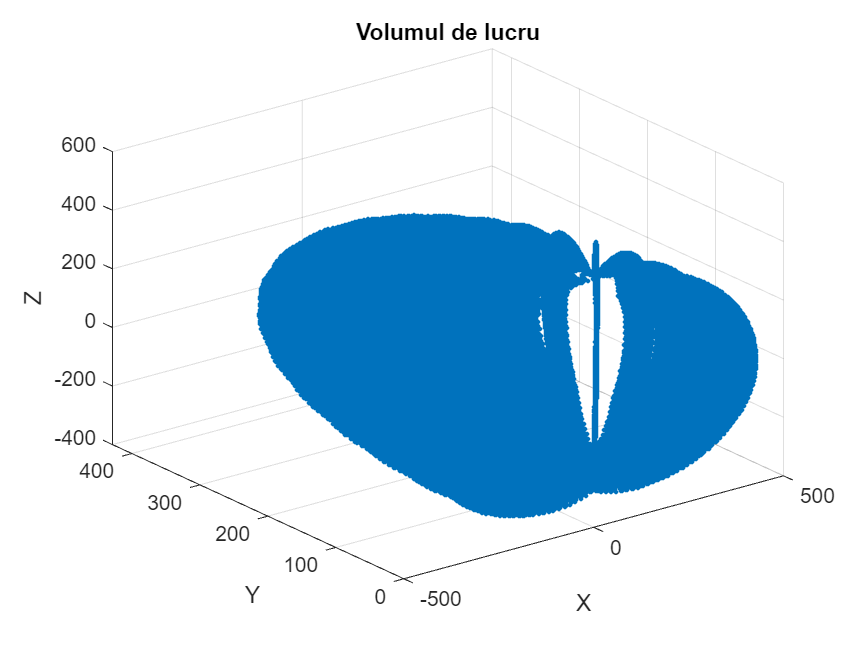

%Volumul de lucru:capacitatea de deplasare a efectorului
Volum_de_lucru();